%%              - Autonomous USV Collision Avoidance Algorithm -               %%
%           This code uses an algorithm based on the Projection Method          %
%                to find a collision free path around an obstacle               %
%                                                                               %
%                Written by Dimitrios Stergianelis on August 2018               %
%                                                                               %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
 
% Clean the workspace and close the open figures
clear
clc
close all
tic;

%% Parameters - Setting up the problem
 
% Start point S (XS, YS)
% XS = 2;
% YS = 1;
XS = 15;
YS = 30;

% Target point T (XT, YT)
% XT = 20;
% YT = 18;
XT = 30;
YT = 45;

% Obstacle representation: circle with centre at (XO, YO) and radius RO
% XO = 10;
% YO = 8;
% RO = 4;
XO = 23;
YO = 36;
RO = 4.429;
 
% Safety radius RB
% Was set equal to the radius of the vessel region (RV), for the simulations
RB = 0.571;
 
%% Core calculations
 
% Position vectors, to be used for plotting
X_pos = XS;
Y_pos = YS;
 
% Find the straight-line equation (Y = a*X+b) connecting the start and
% target points
a = (YS - YT)/(XS - XT);
b = (XS*YT - XT*YS)/(XS - XT);
 
% Find the determinant radius RD
RD = RO + RB;
 
% Plot the centre of the circle
plot(XO, YO, '.b')
hold on
axis equal; box on;
xlabel('X (m)'); ylabel('Y (m)');
 
% Plot the circle (X-XO)^2+(Y-YO)^2=RD^2 with XO, YO and RD red --- line
plot_circle(XO, YO, RD, 'r');
 
% Plot the circle (X-XO)^2+(Y-YO)^2=RO^2 with XO, YO and RO blue --- line
plot_circle(XO, YO, RO, 'b');
 
% Add description (text) to data points
txt1 = ' Start point';
text(XS,YS,txt1,'VerticalAlignment','top')
 
txt2 = ' Target point';
text(XT,YT,txt2,'VerticalAlignment','top')
 
% Check if the vessel is already inside obstacle region
if (sqrt((XS - XO)^2 + (YS - YO)^2) < RD) || (sqrt((XT - XO)^2 + (YT - YO)^2) < RD)
    error('Start/Target point(s) inside obstacle region')
end
 
% Calculate the length of the straight line from S to T
L = sqrt((XT - XS)^2 + (YT - YS)^2);
disp(['Straight-line length: ' num2str(L)])

Straight-line length: 21.2132


 
% Find the intersection point(s) between the line and the circle (equation: (X-XO)^2+(Y-YO)^2 = RD^2)
% Need to solve: (a^2 + 1)*X^2 + 2*(a*b - a*YO - XO)*X + (YO^2 - RD^2 + XO^2 - 2*b*YO + b^2) = 0
% Substitutions in the quadratic equation
A = (a^2 + 1);
B = 2*(a*b - a*YO - XO);
C = (YO^2 - RD^2 + XO^2 - 2*b*YO + b^2);
 
% Determinant calculation
D = B^2 - 4*A*C;
 
%% Finding the relative position between the straight line and the obstacle
 
% Check if the straight line intersects with the obstacle
if ((XS == XT) && ((XS <= XO - RD) || (XS >= XO + RD)))
    % Route parallel to Y-axis and no intersection point
    % Continue moving on the straight line
    NoIntersection = true;
    disp('No Intersection')
    
elseif ((YS == YT) && ((YS <= YO - RD) || (YS >= YO + RD)))
    % Route parallel to X-axis and no intersection point
    % Continue moving on the straight line
    NoIntersection = true;
    disp('No Intersection')
    
elseif (D <= 0) % Check determinant value
    % 0 or 1 solutions, i.e. none or one intersection point
    % Continue moving on the straight line
    NoIntersection = true;
    disp('No Intersection')
    
else % Two solutions (intersection points), with coordinates (X1, Y1) & (X2, Y2)
    if (XS == XT) % Route parallel to Y-axis
        X1 = XS;
        X2 = XS;
        Y1 = YO - sqrt (RD^2 - (XS-XO)^2);
        Y2 = YO + sqrt (RD^2 - (XS-XO)^2);
        
    elseif (YS == YT) % Route parallel to X-axis
        X1 = XO - sqrt (RD^2 - (YS-YO)^2);
        X2 = XO + sqrt (RD^2 - (YS-YO)^2);
        Y1 = YS;
        Y2 = YS;
        
    else % Route with random orientation
        X1 = (-B + sqrt(B^2 - 4*A*C))/(2*A);
        X2 = (-B - sqrt(B^2 - 4*A*C))/(2*A);
        Y1 = a*X1 + b;
        Y2 = a*X2 + b;
    end
    
    % Plot the intersection points
    plot(X1, Y1, 'xk')
    plot(X2, Y2, 'xk')
    
    % Check if the intersection points belong to the line segment from S to T
    if (XT > XS)
        if (XS < X1 && X2 < XT)
            NoIntersection = false;
            disp('Intersection')
        else
            NoIntersection = true;
            disp('No Intersection')
        end
        
    elseif (XT == XS)
        if (YT > YS)
            if (YS < Y1 && Y2 < YT)
                NoIntersection = false;
                disp('Intersection')
            else
                NoIntersection = true;
                disp('No Intersection')
            end
        else % YT < YS
            if (YT < Y1 && Y2 < YS)
                NoIntersection = false;
                disp('Intersection')
            else
                NoIntersection = true;
                disp('No Intersection')
            end
        end
        
    else % XT < XS
        if (XT < X1 && X2 < XS)
            NoIntersection = false;
            disp('Intersection')
        else
            NoIntersection = true;
            disp('No Intersection')
        end
    end
end

Intersection


 
%% Way of updating position vector
 
if (NoIntersection)
    % Continue moving on the straight line
    % Update position vector
    X_pos = [X_pos XT];
    Y_pos = [Y_pos YT];
    
else % Determine the direction to turn
    if (XS == XT) % Extra criterion because in this case YCRIT=YO and cannot determine the direction to turn
        if (XS >= XO)
            if (YS > YO) % First quadrant
                CCW = true;
                disp('First quadrant')
            else % YS < YO Fourth quadrant
                CCW = false;
                disp('Fourth quadrant')
            end
        else % XS < XO
            if (YS > YO) % Second quadrant
                CCW = false;
                disp('Second quadrant')
            else % YS < YO Third quadrant
                CCW = true;
                disp('Third quadrant')
            end
        end
        XC = XS;
        YC = YO;
        
    else % XS not equal with XT
        if (YS == YT)
            YCRIT = YS;
            XC = XO;
            YC = YS;
        else % Calculate the YCRIT
            YCRIT = a*XO + b;
            % Find the line equation (Y = a2*X + b2) which is lateral to the
            % initial one and is crossing from the centre of the obstacle
            a2 = -1/a;
            b2 = (a*YO + XO)/a;
            % Find the cross point of the two lines (XC, YC)
            % Solve the system (Y = a*X + b) and (Y = a2*X + b2)
            XC = (b2 - b)/(a - a2);
            YC = a*XC + b;
        end
        
        % If YCRIT>=YO then turn CCW angle f1 and CW f2
        if (YCRIT >= YO)
            CCW = true;
        else % If YCRIT<YO then turn CW angle f1 and CCW f2
            CCW = false;
        end
    end
    
    % Calculate the distance from the centre of the obstacle to the cross point
    LR = sqrt((XC - XO)^2 + (YC - YO)^2);
    
    % Calculate the distance from the cross point to the circumference
    LM = RD - LR;
    
    % Calculate the distances from start point to cross point
    tmp0 = sqrt((X1 - XS)^2 + (Y1 - YS)^2);
    tmp1 = sqrt((X2 - XS)^2 + (Y2 - YS)^2);
    
    % SET the smaller D1 and the bigger D2
    if (tmp0 < tmp1)
        D1 = tmp0;
        D2 = tmp1;
    else
        D1 = tmp1;
        D2 = tmp0;
    end
    
    % Calculate the distance from (X2, Y2) to the target point
    D3 = L - D2;
    
    % Calculate the distance between the cross points
    LP = sqrt((X1 - X2)^2 + (Y1 - Y2)^2);
    
    % Calculate the length of hypotenuse in the start triangle
    L1 = sqrt(LM^2 + D1^2);
    
    % Calculate the length of hypotenuse in the target triangle
    L2 = sqrt(LM^2 + D3^2);
    
    % Calculate the first and second turn angle
    % If YCRIT>=YO then turn CCW angle f1 and CW f2
    if (CCW == true)
        f1 = atan(LM/D1);
        f2 = -atan(LM/D3);
    else % If YCRIT<YO then turn CW angle f1 and CCW f2
        f1 = -atan(LM/D1);
        f2 = atan(LM/D3);
    end
    
    % Update position vector when there is intersection
    if (XT > XS) % Forward motion
        % Update position vector - first part
        X_pos = [X_pos, (XS + L1*cos(atan(a) + f1))];
        Y_pos = [Y_pos, (YS + L1*sin(atan(a) + f1))];
        
        % Update position vector - second part
        X_pos = [X_pos, (XS + L1*cos(atan(a) + f1) + LP*cos(atan(a)))];
        Y_pos = [Y_pos, (YS + L1*sin(atan(a) + f1) + LP*sin(atan(a)))];
        
        % Update position vector - third part
        X_pos = [X_pos, (XS + L1*cos(atan(a) + f1) + LP*cos(atan(a)) + L2*cos(atan(a) + f2))];
        Y_pos = [Y_pos, (YS + L1*sin(atan(a) + f1) + LP*sin(atan(a)) + L2*sin(atan(a) + f2))];
        
    elseif (XS == XT) % Parallel to Y-axis motion
        % Update position vector - first part
        X_pos = [X_pos, (XS + sign(YS-YO)*L1*cos(pi/2 - f1))];
        Y_pos = [Y_pos, (YS - sign(YS-YO)*L1*sin(pi/2 - f1))];
        
        % Update position vector - second part
        X_pos = [X_pos, (XS + sign(YS-YO)*L1*cos(pi/2 - f1) - sign(YS - YO)*LP*cos(pi/2))];
        Y_pos = [Y_pos, (YS - sign(YS-YO)*L1*sin(pi/2 - f1) - sign(YS - YO)*LP*sin(pi/2))];
        
        % Update position vector - third part
        X_pos = [X_pos, (XS + sign(YS-YO)*L1*cos(pi/2 - f1) - sign(YS - YO)*LP*cos(pi/2) + sign(YS-YO)*L2*cos(pi/2 - f2))];
        Y_pos = [Y_pos, (YS - sign(YS-YO)*L1*sin(pi/2 - f1) - sign(YS - YO)*LP*sin(pi/2) - sign(YS-YO)*L2*sin(pi/2 - f2))];
        
    else % Backward motion
        % Update position vector - first part
        X_pos = [X_pos, (XS - L1*cos(atan(a) - f1))];
        Y_pos = [Y_pos, (YS - L1*sin(atan(a) - f1))];
        
        % Update position vector - second part
        X_pos = [X_pos, (XS - L1*cos(atan(a) - f1) - LP*cos(atan(a)))];
        Y_pos = [Y_pos, (YS - L1*sin(atan(a) - f1) - LP*sin(atan(a)))];
        
        % Update position vector - third part
        X_pos = [X_pos, (XS - L1*cos(atan(a) - f1) - LP*cos(atan(a)) - L2*cos(atan(a) - f2))];
        Y_pos = [Y_pos, (YS - L1*sin(atan(a) - f1) - LP*sin(atan(a)) - L2*sin(atan(a) - f2))];
    end
    
    % Calculate the total distance
    L_travel = L1 + LP + L2;
    disp(['Trajectory length: ' num2str(L_travel)])
    
    % Calculate the extra distance
    L_extra = L_travel - L;
    disp(['Extra distance travelled due to obstacle: ' num2str(L_extra)])
    
end

Trajectory length: 23.2682


Extra distance travelled due to obstacle: 2.055


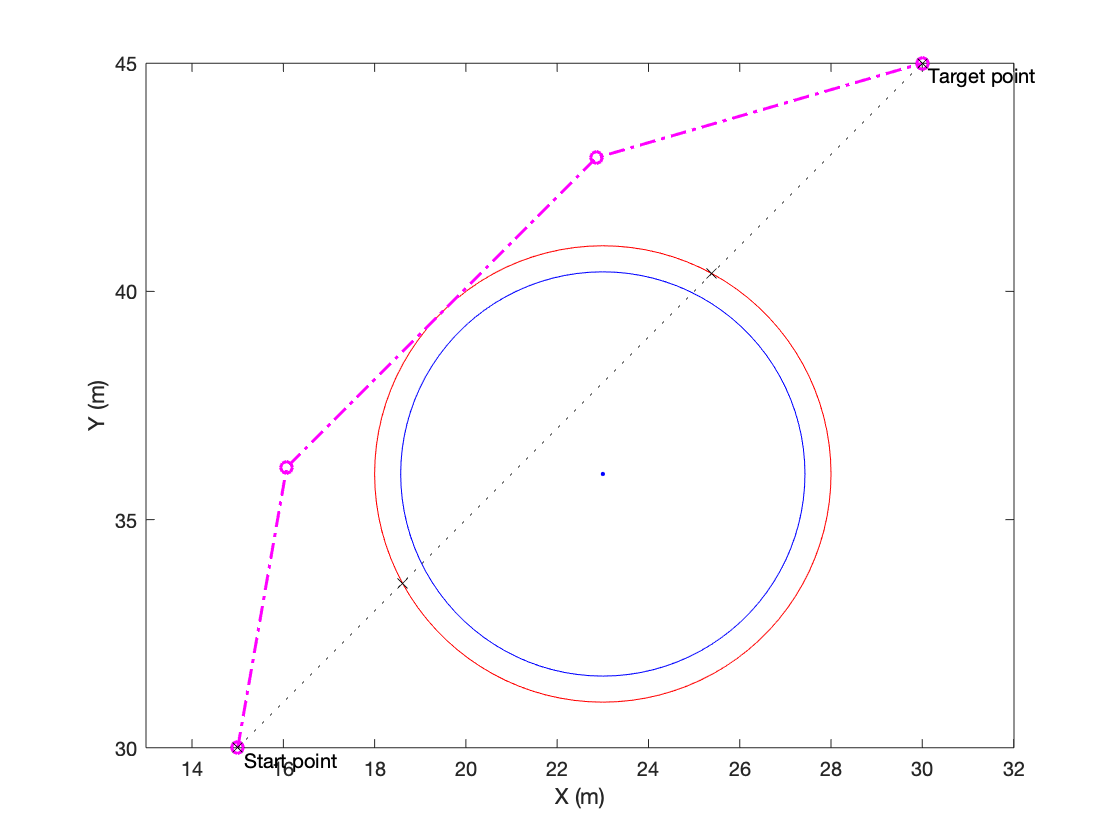

 
% Plot trajectory with magenta dash-dot line
plot(X_pos, Y_pos, '-.om', 'LineWidth', 1.5)
 
% Plot line Y=a*X+b with black dotted line
x = [XS, XT];
y = [YS, YT];
plot (x, y, ':xk')


toc

Elapsed time is 0.231031 seconds.
